close = '230320-009-jump-1.wav';
far = '230320-009-jump-2.wav';
% /home/greven/repos/ES10-Drowning/data/measurment-1/jumps/
[audioDataClose, sr] = audioread(close);
[audioDataFar, sr] = audioread(far);

% Define constants
REF_EFF = 20e-5; % Pa
CAL_SPL = 123.8; % dB
NFFT = 1024;
HOP_LENGTH = 512;
TOP_DB = 80;


% Calculate calibration gain for both paths
calibration_gain_A = calculate_calibration_gain(close, REF_EFF, CAL_SPL);

Calibration file: 230320-009-jump-1.wav
Calibration length: 20.00 seconds
Calibration RMS: -50.58 dB (ref 1 Pa)
Calibration SPL: 23.40 dB (ref 20 uPa)
Calibration gain: -100.40 dB (0.000010)



calibration_gain_B = calculate_calibration_gain(far, REF_EFF, CAL_SPL);

Calibration file: 230320-009-jump-2.wav
Calibration length: 20.00 seconds
Calibration RMS: -59.25 dB (ref 1 Pa)
Calibration SPL: 14.73 dB (ref 20 uPa)
Calibration gain: -109.07 dB (0.000004)



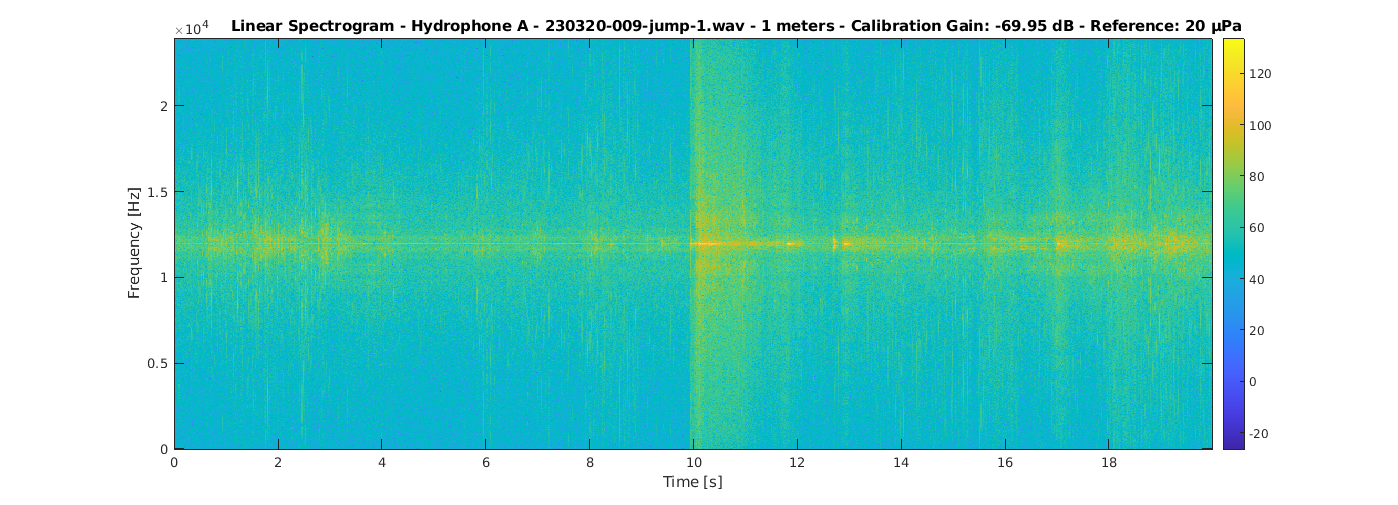


% Load the audio file (assuming stereo)
%[audio, sr] = audioread('audio_file.wav');

% Compute the STFT for both channels
spectrogram_A = stft(audioDataClose(:,1), 'Window', hamming(NFFT, 'periodic'), 'OverlapLength', HOP_LENGTH, 'FFTLength', NFFT);
spectrogram_B = stft(audioDataFar(:,1), 'Window', hamming(NFFT, 'periodic'), 'OverlapLength', HOP_LENGTH, 'FFTLength', NFFT);

% Convert amplitude spectrogram to dB
spectrogram_dB_A = mag2db(abs(spectrogram_A)) - 20 * log10(calibration_gain_A);
spectrogram_dB_B = mag2db(abs(spectrogram_B)) - 20 * log10(calibration_gain_B);

% Determine min and max dB for colormap
min_dB_A = min(spectrogram_dB_A(:));
max_dB_A = max(spectrogram_dB_A(:));
min_dB_B = min(spectrogram_dB_B(:));
max_dB_B = max(spectrogram_dB_B(:));

cmap_min = min([min_dB_A, min_dB_B]);
cmap_max = max([max_dB_A, max_dB_B]);


figure;
imagesc((0:size(spectrogram_dB_A, 2)-1) * HOP_LENGTH / sr, (0:NFFT/2-1) * sr / NFFT, spectrogram_dB_A);
set(gca, 'YDir', 'normal');
colorbar('Limits', [cmap_min cmap_max]);
%colormap('inferno');
title('                 Linear Spectrogram - Hydrophone A - 230320-009-jump-1.wav - 1 meters - Calibration Gain: -69.95 dB - Reference: 20 μPa');
xlabel('Time [s]');
ylabel('Frequency [Hz]');
set(gcf,'Visible','on', 'Units', 'centimeters','OuterPosition', [0 0 37 18])

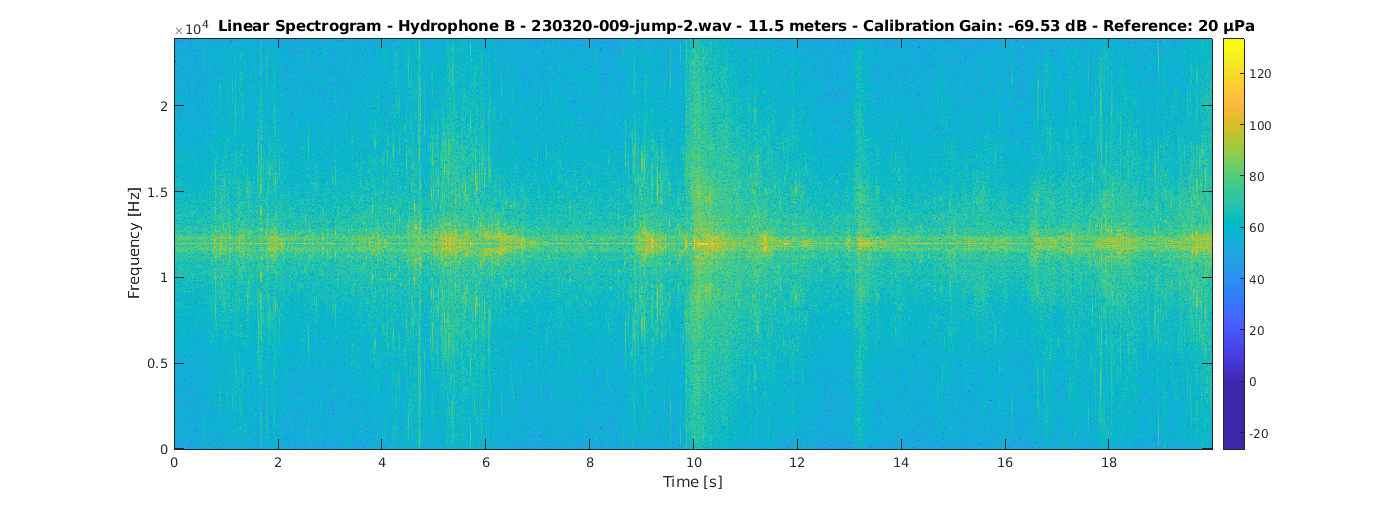

%exportgraphics(gcf,'hydrophoneA.pdf')

figure;
imagesc((0:size(spectrogram_dB_B, 2)-1) * HOP_LENGTH / sr, (0:NFFT/2-1) * sr / NFFT, spectrogram_dB_B);
set(gca, 'YDir', 'normal');
colorbar('Limits', [cmap_min cmap_max]);
%colormap('inferno');
title('                 Linear Spectrogram - Hydrophone B - 230320-009-jump-2.wav - 11.5 meters - Calibration Gain: -69.53 dB - Reference: 20 μPa');
xlabel('Time [s]');
ylabel('Frequency [Hz]');
set(gcf,'Visible','on', 'Units', 'centimeters','OuterPosition', [0 0 37 18])

%exportgraphics(gcf,'hydrophoneB.pdf')


% Function to calculate calibration gain

function calibration_gain = calculate_calibration_gain(calibration_path, ref_eff, cal_spl)
    [calibration, sr] = audioread(calibration_path);
    calibration = mean(calibration, 2); % Ensure mono
    length_sec = length(calibration) / sr;
    
    calibration_rms = sqrt(mean(calibration.^2));
    calibration_rms_db = 20 * log10(calibration_rms / 1);
    calibration_spl = 20 * log10(calibration_rms / ref_eff);

    gain_db = calibration_spl - cal_spl;
    calibration_gain = 10^(gain_db / 20);

    fprintf('Calibration file: %s\n', calibration_path);
    fprintf('Calibration length: %.2f seconds\n', length_sec);
    fprintf('Calibration RMS: %.2f dB (ref 1 Pa)\n', calibration_rms_db);
    fprintf('Calibration SPL: %.2f dB (ref 20 uPa)\n', calibration_spl);
    fprintf('Calibration gain: %.2f dB (%.6f)\n\n', gain_db, calibration_gain);
end
